Want to visualize how the squares split up the adjacency matrix

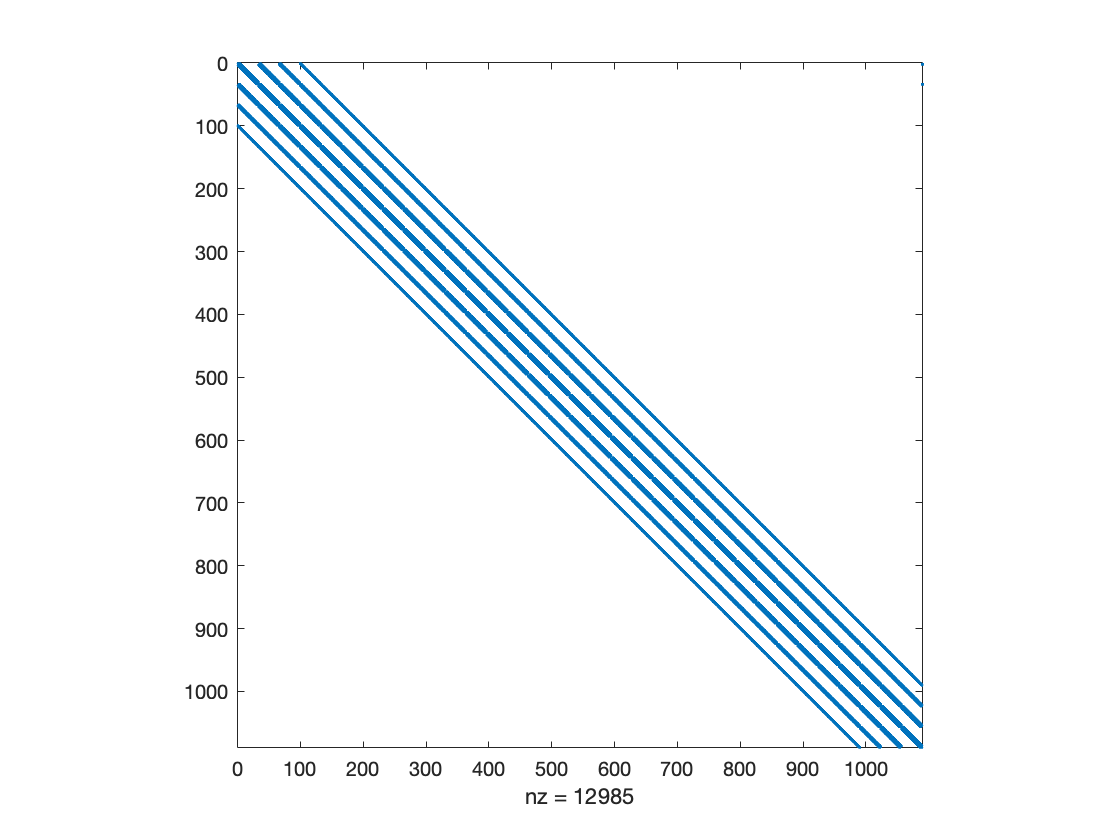

addpath('Subroutines')
clear

% Parameters needed to generate grid
x0 = -1; x1 = 1;
y0 = -1; y1 = 1;
N = 2^5+1;
h = (x1-x0)/(N+1);

% requirement: overlap + depth - 1 <= (N-1)/2
depth = ceil(h^(-1/3));
overlap = ceil(sqrt(depth)*(N-1)/20);

if (overlap + depth - 1 > (N-1)/2)
   error("overlap + depth exceeds mesh size")
end
% for around 10% overlap, choose overlap ~ (N-1)/20 



% Call mesh builder
[Points,Interior,Boundary,NMatSDD,CMatSDD,theta] = buildMesh_Rect(x0,x1,y0,y1,h,depth);

% solver settings
order = 2;
epsilon = (h*depth)^2;
weight = quadWeights(theta,order);
delta = h*overlap;

Dvvs = cell(length(theta),1);
for k = 1:length(theta)
   Dvvs{k} = sparse( repmat(Interior,1,3), [NMatSDD(:,k*3-2) NMatSDD(:,k*3-1) NMatSDD(:,k*3)], [CMatSDD(:,k*3-2) CMatSDD(:,k*3-1) CMatSDD(:,k*3)], length(Interior), length(Points));
end 

adj = zeros(length(Interior),length(Points));
for k = Interior
    for j = 1:size(NMatSDD,2)
        adj(k,NMatSDD(k,j)) = 1;
    end
end

spy(adj)
Adj = adj(Interior,Interior);
spy(Adj)

[subInd,subOL] = fourSquares(x0,x1,y0,y1,delta,Points,Interior);

% creates a struct array of each local discretization
Doms = subDoms(NMatSDD,CMatSDD,Dvvs,subInd,subOL,zeros(length(Interior),1),zeros(length(Points),1));

We split the interior of the domain into 4 disjoint subdomains, the global indices of the points in each of these subdomains is found in subInd. We can visualize this

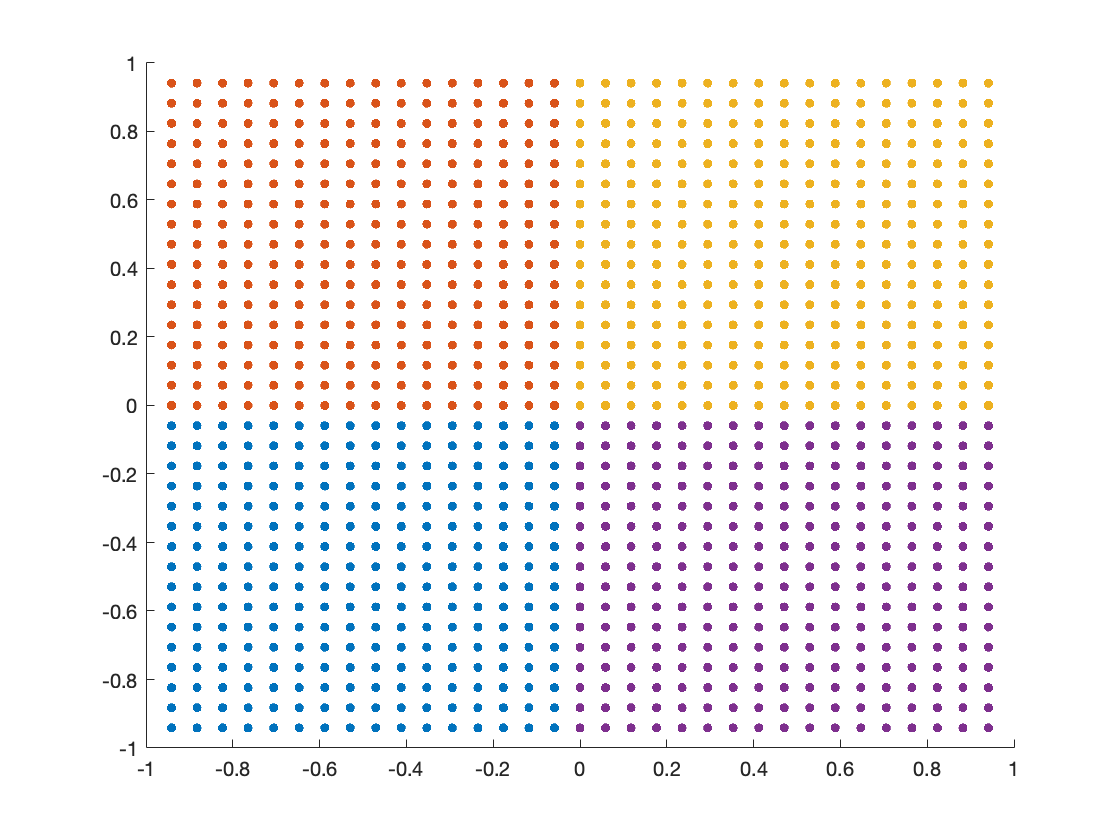

figure, hold on
for k = 1:4
plot(Points(subInd{k},1),Points(subInd{k},2),'.','MarkerSize',12)
end

We can view the artificial interface as being some lines which lie between the subdomains, however we don't sample along it. We then extend each subdomain out by delta = h*overlap, the global indices of these points are denoted by subOL. The collection of points in both subInd and subOL form the interior of the sub PDE problem. We graph the overlap extension of just a single subdomain 

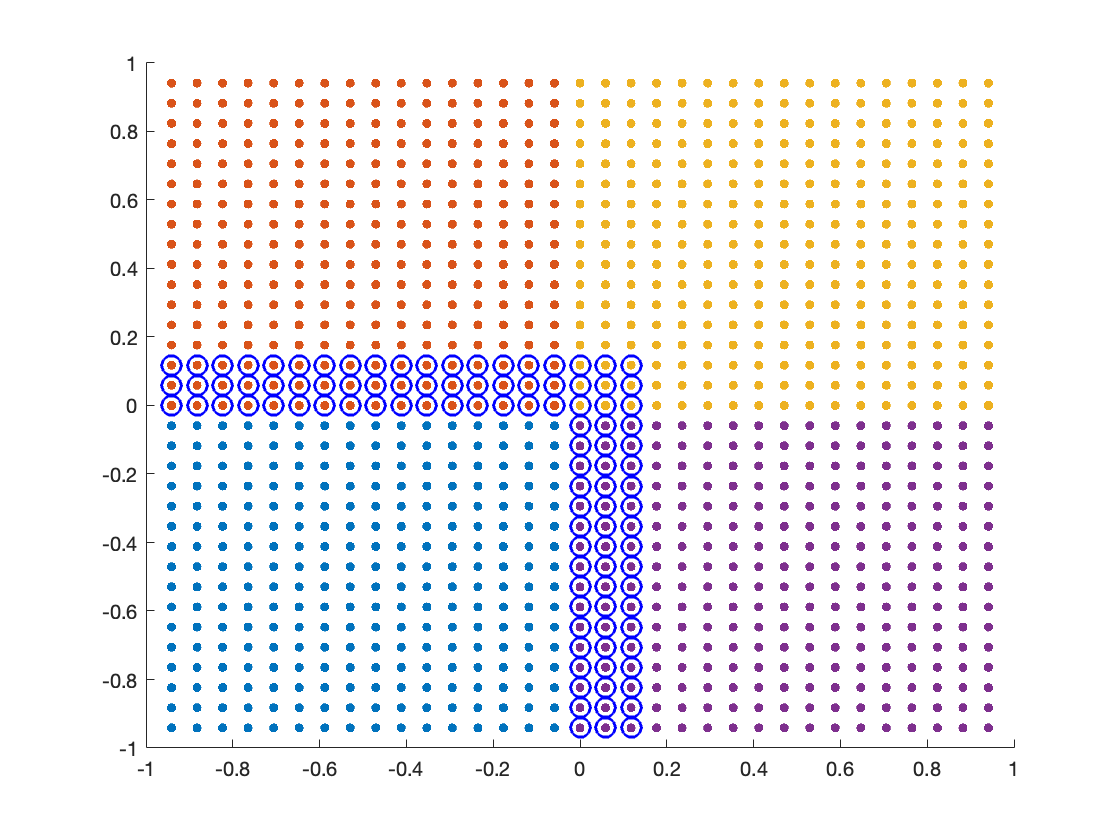

figure, hold on
for k = 1:4
plot(Points(subInd{k},1),Points(subInd{k},2),'.','MarkerSize',12)
end
plot(Points(subOL{1},1),Points(subOL{1},2),'ob','MarkerSize',10,'LineWidth',1.5)

The collection of both subInd and subOL form the interior of the sub PDE problem. We the build the boundary by taking the neighboring points from NMatSDD (globally). For a given index 'i' , the set of indices in NMatSDD(i,:) are all of the neighbors, whether they are in the interior or the boundary. This automatically recovers the "strip" boundary data. Note that it's not exactly a rectangular strip, as it only calls data which actually appears in the stencils. We currently don't distinguish from sub boundary data which comes from the strip or from the actual boundary. When we form a global solution, we only take values from the disjoint subdomains. 

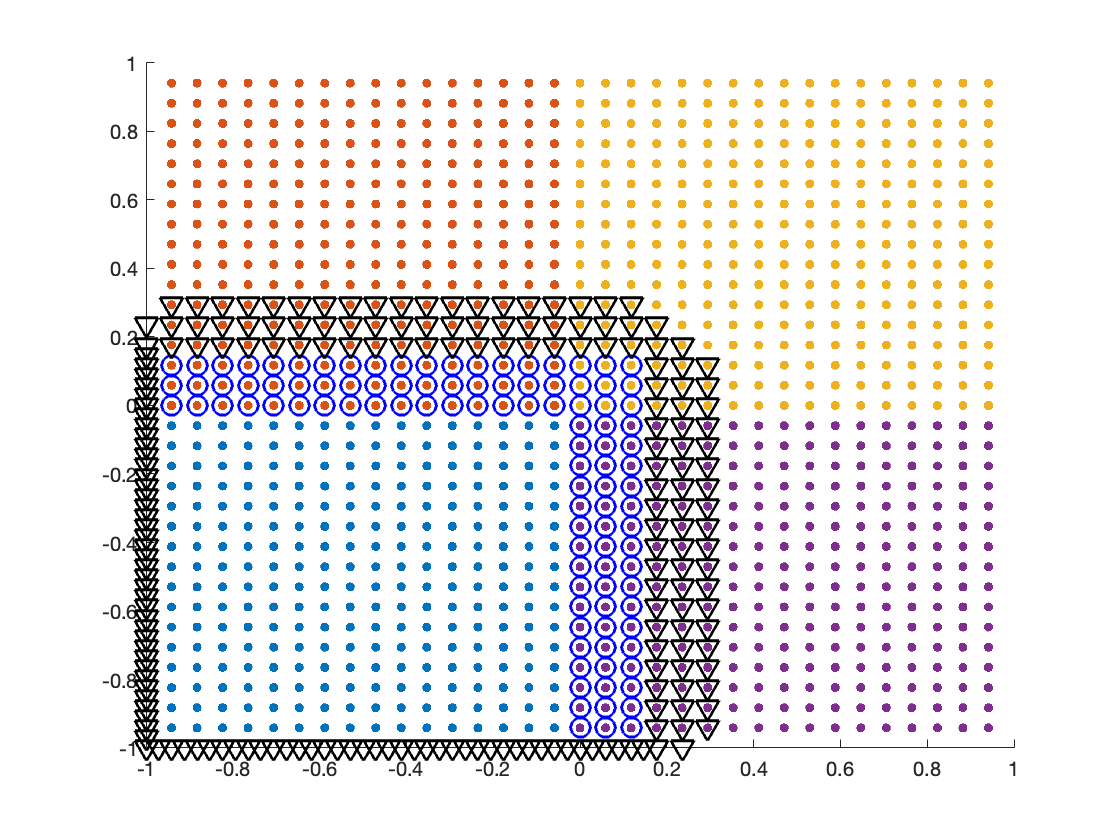

figure, hold on
for k = 1:4
plot(Points(subInd{k},1),Points(subInd{k},2),'.','MarkerSize',12)
end
plot(Points(subOL{1},1),Points(subOL{1},2),'ob','MarkerSize',10,'LineWidth',1.5)
plot(Points(Doms(1).B_g,1),Points(Doms(1).B_g,2),'vk','MarkerSize',10,'LineWidth',1.5)

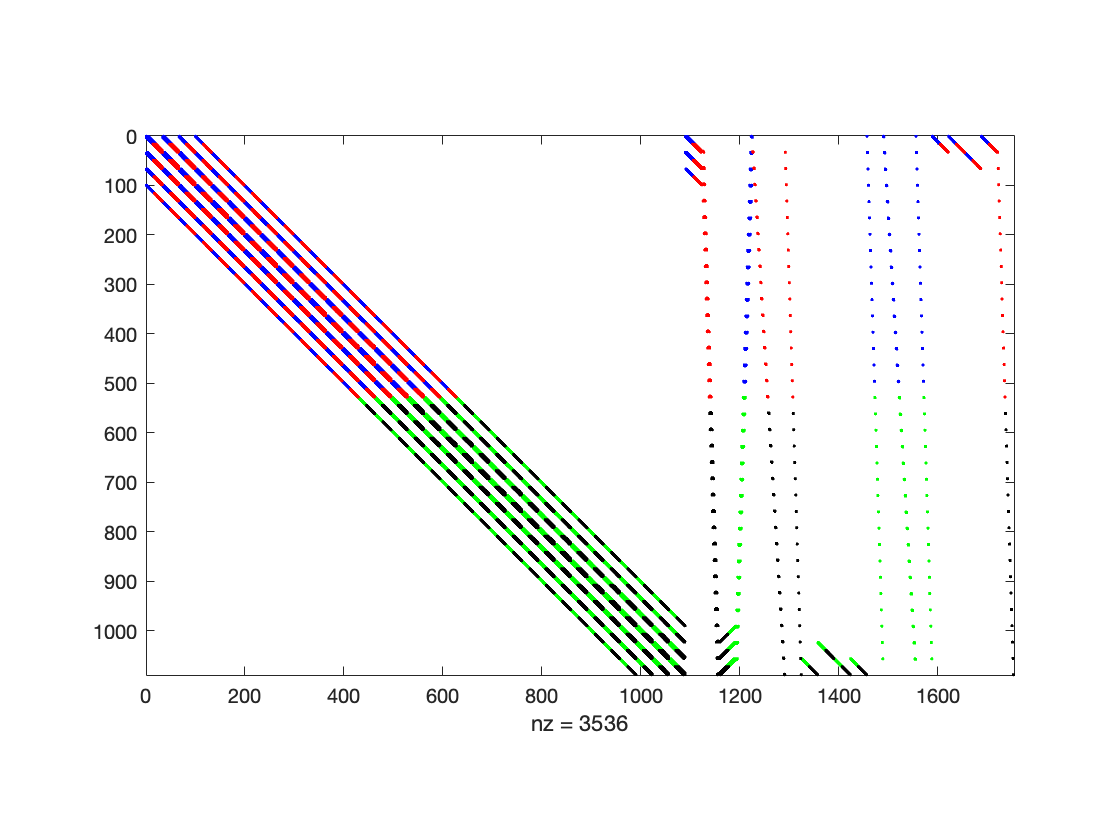




sub_adj = cell(1,4);
sub_Adj = sub_adj;

for k = 1:4
    sub_adj{k} = zeros(size(adj));
    sub_adj{k}(subInd{k},:) = adj(subInd{k},:);
    sub_Adj{k} = sub_adj{k}(:,Interior);
end

figure
spy(sub_adj{1},'b')
hold on
spy(sub_adj{2},'g')
spy(sub_adj{3},'k')
spy(sub_adj{4},'r')

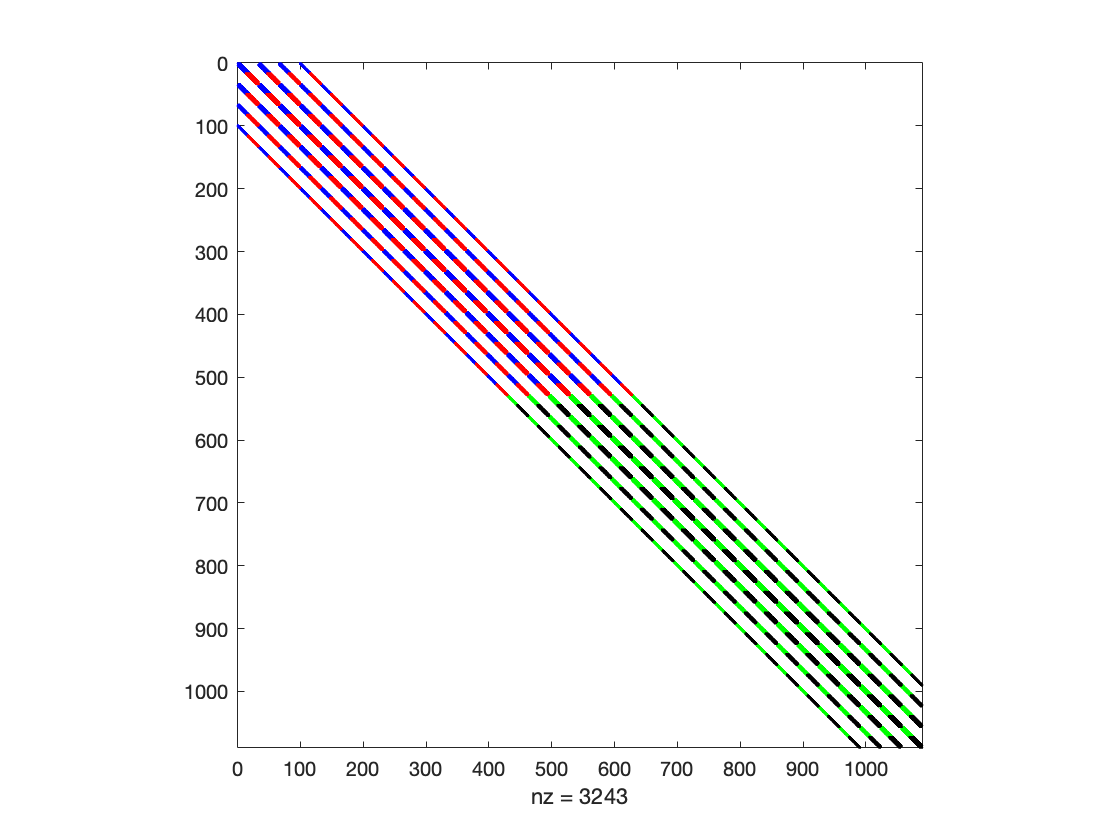

figure
spy(sub_Adj{1},'b')
hold on
spy(sub_Adj{2},'g')
spy(sub_Adj{3},'k')
spy(sub_Adj{4},'r')